%2025.09.03
%产生瞄准干扰作为分类数据，20-40Mhz带宽
close all;clear;clc
j=sqrt(-1);
data_num=1;     %干扰样本数
samp_num=8000;  %距离窗点数

fs = 80e6;      %采样频率 80MHz
ts = 1/fs;      %采样时间间隔
B  = 10e6;      %信号带宽 10MHz
taup = 20e-6;   %信号脉宽 
t = linspace(0,taup,taup*fs);          %时间序列

fc = 40e6       %信号中心频率 40MHz

fc = 40000000

Bj = 20

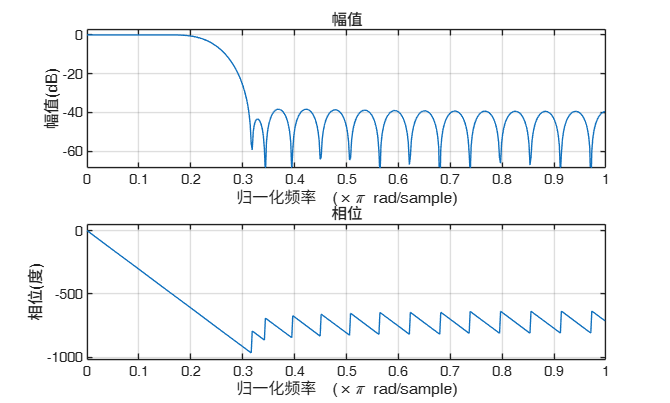

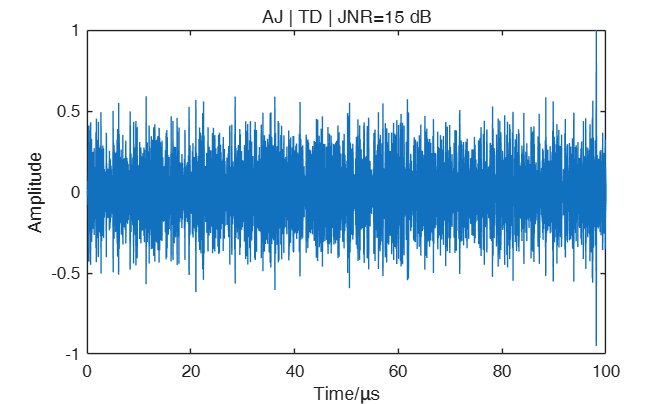

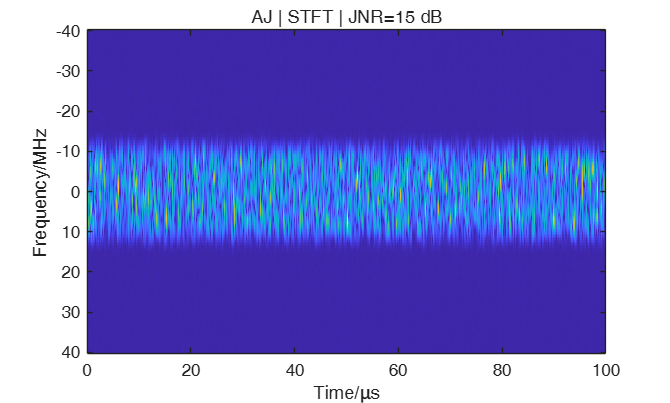

f0 = fc - B/2;   % 起始频率
f1 = fc + B/2;   % 终止频率
lfm = exp(1j*2*pi*(f0*t + (B/(2*taup))*t.^2));


SNR=15; %信噪比dB
echo=zeros(data_num,samp_num,3);     %矩阵大小（500,samp_num,2）
echo_stft=zeros(data_num,100,247,3);  %矩阵大小（500,200,1000,2）
num_label = 5;
label=zeros(1,data_num)+num_label;                         %标签数据,此干扰标签为0

for m=1:data_num
    
    JNR=50; %干噪比50dB
    % JNR=30+round(rand(1,1)*30); %干噪比30-60dB
    range=round(rand(1,1)*1500);%瞄频噪声干扰起始点
    Bj=20 %瞄准带宽固定20MHz
    %Bj=20+round(rand(1,1)*20);%瞄频带宽20-40MHz
    sp=randn([1,samp_num])+1j*randn([1,samp_num]);%噪声基底
    sp=sp/std(sp);
    white_noise = sp;
    sp1=sp;
    As=10^(SNR/20);%目标回波幅度
    Aj=10^(JNR/20);  %干扰回波幅度

    fjc = 40e6;       % 瞄准的中心频率
    lpFilt = fir1(34, Bj*1e6/(fs),chebwin(35,30)); 
    freqz(lpFilt,1)
    sp1 = filter(lpFilt, 1, sp1);
    tj = (0:samp_num-1)/fs;
    sp1 = sp1 .* exp(1j*2*pi*fjc*tj);  % 频移

    % sp1_fft=fftshift(fft(sp1));
    % sp1_fft(1:round(samp_num*((1-Bj/80)/2)))=0;
    % sp1_fft(round(samp_num*((1-Bj/80)/2))+round(Bj/80*samp_num):samp_num)=0;
    % sp1=ifftshift(ifft(sp1_fft));

    range_tar=1+round(rand(1,1)*1400);

    sp(1+range_tar:length(lfm)+range_tar)=sp(1+range_tar:length(lfm)+range_tar)+As*lfm;  
    pure_echo = 0*sp;
    pure_echo(1+range_tar:length(lfm)+range_tar) = pure_echo(1+range_tar:length(lfm)+range_tar)+As*lfm;
    noise_echo = Aj*sp1;
    %噪声+目标回波 目标在距离窗内range点处
    sp=sp+Aj*sp1; 
    sp=sp/max(max(sp));
    sp_abs=abs(sp);
    figure(3)
    plot(linspace(0,100,samp_num),sp);
    title(sprintf('AJ | TD | JNR=%d dB', SNR));
    xlabel('Time/μs'); ylabel('Amplitude');
    echo(m,1:samp_num,1)=real(sp); 
    echo(m,1:samp_num,2)=imag(sp);
    echo(m,1:samp_num,3)=sp_abs;
    echo(m,1:samp_num,4)=angle(sp); %信号实部、虚部分开存入三维张量中
    
    % [S,F,T] = stft(sp,fs,'Window',hamming(window),'OverlapLength',window/2,'FFTLength',nfft,'FrequencyRange','centered');
    [S,F,T] = spectrogram(sp,32,32-8,200,fs);
    
    S=S/max(max(S));
    S_abs=abs(S);
     figure(4)
    imagesc(linspace(0,100,size(S,1)), linspace(-40,40,size(S,2)),abs(S));
    % axis([0 100 -20 20])
    title(sprintf('AJ | STFT | JNR=%d dB', SNR)); 
    ylabel('Frequency/MHz'); xlabel('Time/μs');


    echo_stft(m,1:size(S,1),1:size(S,2),1)=real(S);
    echo_stft(m,1:size(S,1),1:size(S,2),2)=imag(S);
    echo_stft(m,1:size(S,1),1:size(S,2),3)=S_abs;
    echo_stft(m,1:size(S,1),1:size(S,2),4)=angle(S);

 
    
end

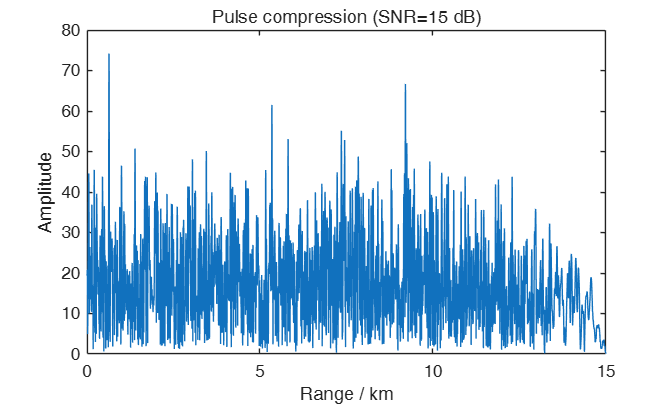


% --- 匹配滤波脉冲压缩 ---
s_ref = lfm;                    % 参考信号 (一定要和生成时一致)
h = conj(flip(s_ref));
y = conv(sp, h);
Np = length(s_ref);
y_aligned = y(Np:end);          % 对齐
env = abs(y_aligned);
env_dB = 10*log10(env.^2 / max(env.^2));


% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * c/(2*fs);

% 绘图
figure;
% plot(rng_axis*1e-3, env_dB);
% xlabel('Range / km'); ylabel('Power (dB)');

plot(rng_axis*1e-3, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression (SNR=%d dB)', SNR));